# Single-Track Vehicle Model

*by Ing. Denis Efremov*

## Introduction

Compared to the previously discussed kinematic model of a vehicle, the single-track (a.k.a. *bicycle model*) uses car's dynamics as its core function. This model is more precise comparing the real car physics. However, it is still based according some assumptions, namelly:

- all lifting, rolling, and pitching motion are neglected,

- vehicle mass is assumed to be concentrated at the center of gravity,

- front and rear tires are represented as one single tire on each axle; imaginary contact points of tires and surface are assumed to lie along the center of axles,

- pneumatic trail and aligning torque resulting from a sideslip angle of a tire are neglected,

- mass distribution on the axles is assumed to be constant.

There is a way to augment a basic single-track model for each assumption. Those augmentations could lead to a more precise vehicle model (and more complex). Commonly those tries end with a twin-track model [1] (or even multibody model [2]), which will not be considered during this course. The basic single-track model can be analyzed on the 0-2 Hz frequency spectrum [2], which suits to control, for example, lateral vehicle dynamics.

## General Idea

The core idea of the single-track is lumping together both wheels on each axle and describing forces that act on each tire/wheel. The vehicle is assumed to be one mass point, placed at the center of gravity (CG). Tires and wheels act on the rigid body dynamics by traction forces $F_{\rm x,f}$, $F_{\rm y,f}$, $F_{\rm x,r}$, $F_{\rm y,r}$. Whole vehicle dynamics is then described using states:

- $v$ (m/s, magnitude of the velocity vector),

- $\beta$ (rad, sideslip angle),

- $r$ (rad/s, yaw rate, or how fast the vehicle rotates around its CG),

- $\omega_{\rm f}$ (rad/s, angular velocity of the front axle),

- $\omega_{\rm r}$ (rad/s, angular velocity of the rear axle),

- $x_{\rm pos}$ (m, x coordinate of the position of CG),

- $y_{\rm pos}$ (m, y coordinate of the position of CG),

- $\psi$ (rad, heading of the vehicle).

The last three states are the same as in the kinematic vehicle model. It serves to work with vehicle position and could be omitted when we are not interested in it.

Inputs, which are assumed:

- $\delta_{\rm f}$ (rad, steering angle of the front axle),

- $\delta_{\rm r}$ (rad, steering angle of the rear axle),

- $\tau_{\rm df}$ (Nm, driving torque applied on the front axle),

- $\tau_{\rm bf}$ (Nm, braking torque applied on the front axle),

- $\tau_{\rm dr}$ (Nm, driving torque applied on the rear axle),

- $\tau_{\rm br}$ (Nm, braking torque applied on the rear axle).

Most braking and traction control systems algorithms work with drive and braking torques. However, in some systems, when we are not interested in wheel dynamics, one can use wheels' angular velocities as inputs of the model instead of torques, reducing by this step two dynamical equations from the core dynamics.

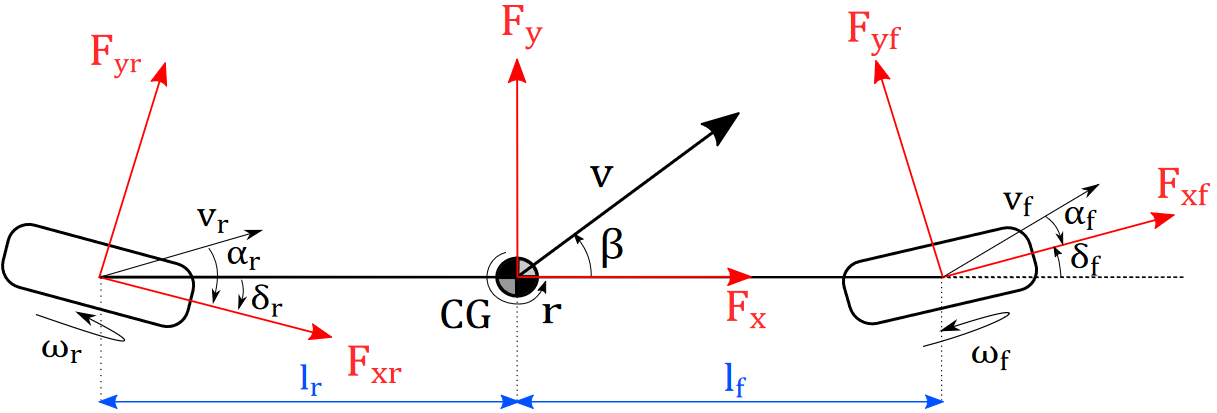Fig.1: Schematic model of a car. Source: [3]

The whole vehicle model can be separated into the following block for simplicity (see block diagram below). Each block has its purpose:

- **rigid body dynamics**, which represents a chassis;

- **steering angles projection** block computes longitudinal and lateral forces and angular momentum acting on the rigid body**;**

- **tire models** block calculates tire forces from slip variables;

- **wheel kinematics**, which calculates sideslip angles of the tires in the particular coordinate frame;

- **slip ratios **calculation part, which computes how each wheel spins;

- **wheel dynamics **part stands for the wheel rotational dynamics.

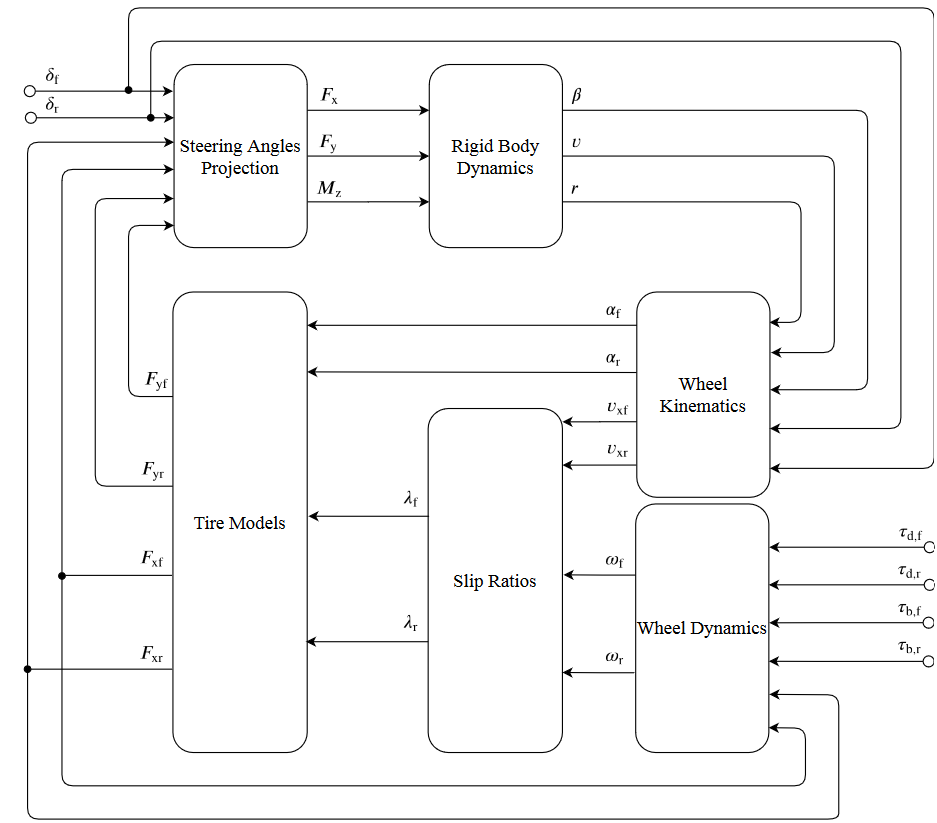Fig.2: Block-diagram of the single-track model. Source: [3]

## Tasks list

Your task is to implement each block as a code function and combine the whole vehicle model.

1) Implement riding body dynamics. What numerical problem can arise here?

 "Division by 0"

 Try to solve it using the if-else statement.

2) Implement steering angle projection calculation.

3) Implement tire model block. Assume a two-lines model for both forces for each axle:

 
$$F = \begin{cases} c \cdot \alpha, when |\alpha| < \frac{F_{max}}{c},\\ F_{max}, when |\alpha| \geq \frac{F_{max}}{c}.\end{cases} $$
 

4) Implement wheel kinematics calculation.

5) Implement wheel dynamics.

6) Implement a block for slip ratio calculation.

7) Combine everything in one function. Do not forget to augment your model with position coordinates of the CG and vehicle's heading angle, as done in the kinematic model.

8) Answer the following questions: 

-  Will this car model stops without applying braking torque on any axle?

-  What is a general source of braking (except inputs) in vehicle dynamics?

-  How could they be introduced in this model?

-  Does the model work well around zero velocity?

## Simulation ride tests

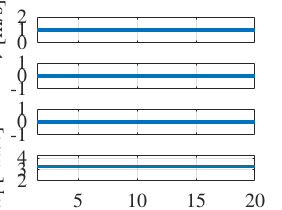

load('single_track_data.mat')
% initialize car parameters
initCar; 

% crop data from CarMaker
start_time = 1500;
t_taken = start_time:20000;

% states of the model will be stored here
vode = zeros(length(inputs.Data(t_taken,1)),1);
betaode = zeros(length(inputs.Data(t_taken,1)),1);
rode = zeros(length(inputs.Data(t_taken,1)),1);
wfode = zeros(length(inputs.Data(t_taken,1)),1);
wrode = zeros(length(inputs.Data(t_taken,1)),1);
xode = zeros(length(inputs.Data(t_taken,1)),1);
yode = zeros(length(inputs.Data(t_taken,1)),1);
psiode = zeros(length(inputs.Data(t_taken,1)),1);

% simulation time
time = inputs.Time(t_taken,1);

% ODE settings
options_ode = odeset('Maxstep', 10e-4, 'MaxOrder', 5, 'AbsTol', 1e-7);

% simulation
x_prev = [1, 0, 0, 1/car.rad, 1/car.rad, 0, 0, 0]; % init state
vode(1) = x_prev(1);
betaode(1) = x_prev(2);
rode(1) = x_prev(3);
wfode(1) = x_prev(4);
wrode(1) = x_prev(5);
xode(1) = x_prev(6);
yode(1) = x_prev(7);
psiode(1) = x_prev(8);
for k = 1:length(time)-1
    u = inputs.Data(start_time+k,:);
    [~, x] = ode15s(@single_track, [time(k) time(k+1)], x_prev, options_ode, u, car);
    vode(k+1) = x(end,1);
    betaode(k+1) = x(end,2);
    rode(k+1) = x(end,3);
    wfode(k+1) = x(end,4);
    wrode(k+1) = x(end,5);
    xode(k+1) = x(end,6);
    yode(k+1) = x(end,7);
    psiode(k+1) = x(end,8);
    x_prev = x(end,:);
end

% plotting
figure
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');
subplot(4,1,1)
plot(time, vode, 'linewidth', 2)
xlim([1.5,20])
grid on
set(gca,'xticklabel',[])
ylabel('$v$ [m/s]', 'Interpreter','latex')
subplot(4,1,2)
plot(time, betaode, 'linewidth', 2)
xlim([1.5,20])
grid on
set(gca,'xticklabel',[])
ylabel('$\beta$ [rad]', 'Interpreter','latex')
subplot(4,1,3)
plot(time, rode, 'linewidth', 2)
xlim([1.5,20])
grid on
set(gca,'xticklabel',[])
ylabel('$r$ [rad/s]', 'Interpreter','latex')
subplot(4,1,4)
plot(time, wfode, 'linewidth', 2)
xlim([1.5,20])
grid on
ylabel('$\omega_{\rm f}$ [rad/s]', 'Interpreter','latex')
xlabel('time [s]', 'Interpreter','latex')

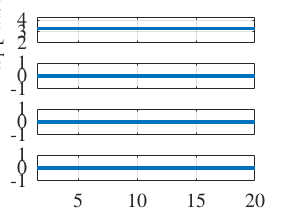


figure
subplot(4,1,1)
plot(time, wrode, 'linewidth', 2)
xlim([1.5,20])
grid on
set(gca,'xticklabel',[])
ylabel('$\omega_{\rm r}$ [rad/s]', 'Interpreter','latex')
subplot(4,1,2)
plot(time, xode, 'linewidth', 2)
xlim([1.5,20])
grid on
set(gca,'xticklabel',[])
ylabel('$x$ pos [m]', 'Interpreter','latex')
subplot(4,1,3)
plot(time, yode, 'linewidth', 2)
xlim([1.5,20])
grid on
ylabel('$y$ pos [m]', 'Interpreter','latex')
set(gca,'xticklabel',[])
subplot(4,1,4)
plot(time, psiode, 'linewidth', 2)
xlim([1.5,20])
grid on
ylabel('$\psi$ [rad]', 'Interpreter','latex')
xlabel('time [s]', 'Interpreter','latex')


% x = [v, beta, r, wf, wr, xpos, ypos, psi] - states of the model
% u = [df, dr, Tdf, Tbf, Tdr, Tbr] - inputs of the model
% car = vehicle parameters see initCar.m for a description

% Definition of functions must be at the end of the script

function [dv, dbeta, dr] = rigid_body_dynamics(Fx, Fy, Mz, x, car)
    % inputs: Fx - longitudinal force at CG
    %         Fy - lateral force at CG
    %         Mz - rotation torque around CG
    %         x - vehicle states
    %         car - car parameters

    MatrixA = [1/car.m*x(0) 0 0; 0 1/car.m  1; 0 0 1/car.Iz];
    RotationMatrix = [-sin(beta) cos(beta) 0; cos(beta) sin(beta) 0; 0 0 1];
    Load = [Fx; Fy; Mz];
    Load2 = [r;0;0];
    result = MatrixA*RotationMatrix*Load - Load2;
    dv    = result(2);
    dbeta = result(1);
    dr    = result(3);
end

function [Fx, Fy, Mz] = steering_angle_projection(Fxf, Fyf, Fxr, Fyr, u, car)
    % inputs: Fxf - longitudinal force at the front axle
    %         Fyf - lateral force at the front axle
    %         Fxr - longitudinal force at the rear axle
    %         Fyr - lateral force at the rear axle
    %         Fy - lateral force at CG
    %         x - model states
    %         u - model inputs
    %         car - car parameters

    Fx = 0;
    Fy = 0;
    Mz = 0;
end

function [Fxf, Fyf, Fxr, Fyr] = tire_models(af, ar, lambdaF, lambdaR, car)
    % inputs: af - sideslip angle of the front wheel
    %         ar - sideslip angle of the rear wheel
    %         lambdaF - slip ratio of the front wheel
    %         lambdaR - slip ration of the rear wheel
    %         car - car parameters
    
    Fxf = 0;
    Fyf = 0;
    Fxr = 0;
    Fyr = 0;
end

function [af, ar, vxf, vxr] = wheel_kinematics(x, u, car)
    % inputs: x - model states
    %         u - model inputs
    %         car - car parameters    

    % TIP: to avoid numerical problems, use atan2

    vxf = 0;
    vxr = 0;
    af = 0;
    ar = 0;
end

function [dwf, dwr] = wheel_dynamics(x, u, Fxf, Fxr, car)
    % inputs: x - model states
    %         u - model inputs
    %         car - car parameters    

    dwf = 0;
    dwr = 0;
end

function [lambdaF, lambdaR] = slip_ratios(vxf, vxr, x, car)
    % inputs: vxf - longitudinal travel velocity of the front axle
    %         vxr - longitudinal travel velocity of the rear axle
    %         x - model states
    %         u - model inputs
    %         car - car parameters    

    lambdaF = 0;
    lambdaR = 0;
end

function xdot = single_track(time, x, u, car)  
    % x = [v, beta, r, wf, wr, xpos, ypos, psi] - states of the model
    % u = [df, dr, Tdf, Tbf, Tdr, Tbr] - inputs of the model
    % car = vehicle parameters
    
    dv = 0;
    dbeta = 0;
    dr = 0;
    dwf = 0;
    dwr = 0;
    dx = 0;
    dy = 0;
    dpsi = 0;
    
    xdot = [dv, dbeta, dr, dwf, dwr, dx, dy, dpsi]';
end

### References

[1] V. Cibulka, Twin-track model implementation. Available online at *https://github.com/SDS-RC-FEE-CTU-in-Prague/TwinTrack*.

[2] D. Schramm, M. Hiller, and R. Bardini, *Vehicle dynamics, Modeling and Simulation*. Springer, 2014.

Equations are there: Full-model -> PDF

[3] D. Efremov, Single-track model implementation. Available online at *https://github.com/SDS-RC-FEE-CTU-in-Prague/SingleTrack*.